# **Video Processing: Laboratory 1:**

Adrià Garcia Coscolla: u232256

Ernest Fosch Muntané: u196572

### **Task 1.a:**

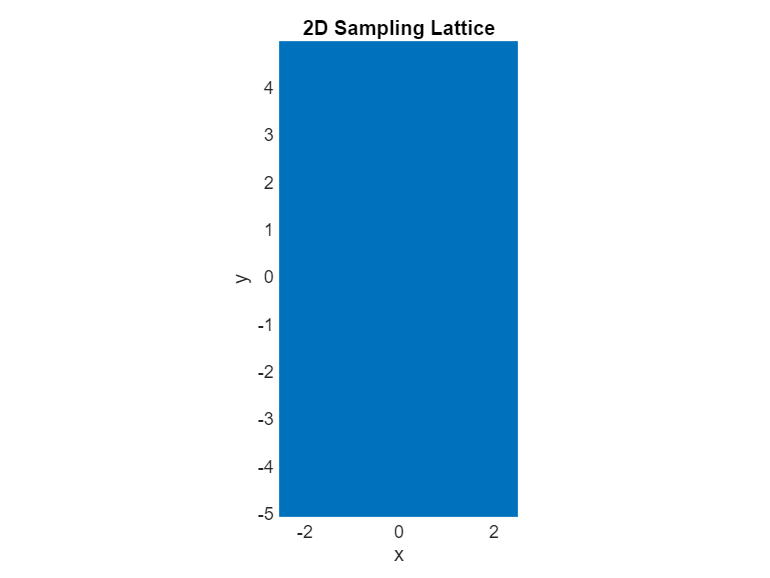

a=6;
b=2;
N=200; %We will have NxN samples if N is even or (N-1)x(N-1) if is odd.

[m,n]= meshgrid(-floor(N/2):floor(N/2)-1); %integer grid

psi= @(x,y)cos(2*pi*a*x) .* cos(2*pi*b*y) + ...
0.7*sin(pi*a*b*(x+y)) + ...
0.5*cos(pi*(a + 0.5*a*b)*x - pi*b*y); 

%sampling lattice:
V=[1/40,0;0,1/20];
% sampling grid, because V is diagonal:
x = V(1,1)*m;
y = V(2,2)*n;

psi_s = psi(x, y); %sampling of the function: psi_s = psi(Vn)

%2D plot of the sample lattice grid.
figure;
voronoi(x, y)
% plot(x,y, '.', 'MarkerSize', 20,'Color', 'b');
title('2D Sampling Lattice');
xlabel('x'); ylabel('y');
axis equal tight;
grid on;

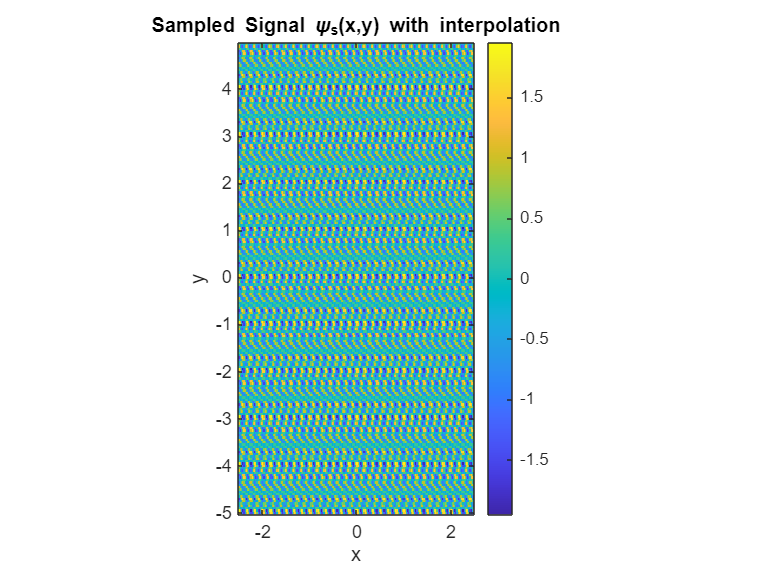


%2D plot of the sampled signal (psi_s)
figure;
imagesc(x(1,:), y(:,1), psi_s);
title('Sampled Signal \psi_s(x,y) with interpolation');
xlabel('x'); ylabel('y');
colorbar;
axis xy; %y pointing up
axis equal tight;

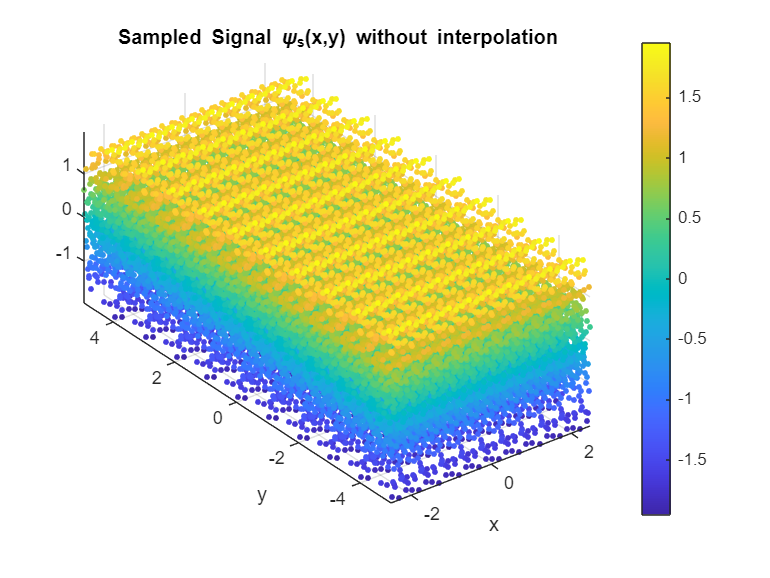

scatter3(x(:), y(:), psi_s(:), 10, psi_s(:), 'filled');
title('Sampled Signal \psi_s(x,y) without interpolation');
xlabel('x'); ylabel('y');
colorbar;
axis xy; %y pointing up
axis equal tight;

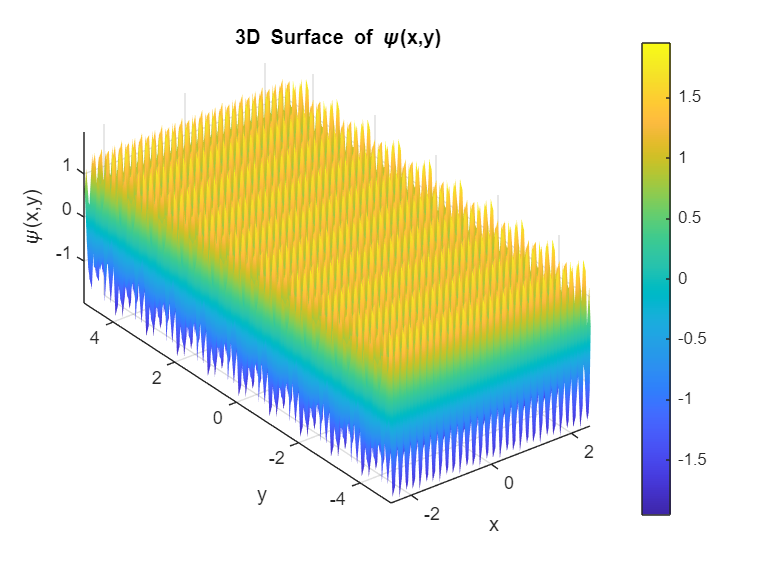



%3D plot of the sampled signal (psi_s)
figure;
surf(x, y, psi_s); % 3D surface
shading interp; % smooth shading
colorbar; % show color scale
axis equal;
xlabel('x'); ylabel('y'); zlabel('\psi(x,y)');
title('3D Surface of \psi(x,y)');


%Another way to create the sampling lattice grid:
%m = -floor(N/2)*V(1,1):V(1,1):(floor(N/2)-1)*V(1,1);
%n = -floor(N/2)*V(2,2):V(2,2):(floor(N/2)-1)*V(2,2);
%   [x,y]= meshgrid(m, n); %integer grid

**Task 1.b:**

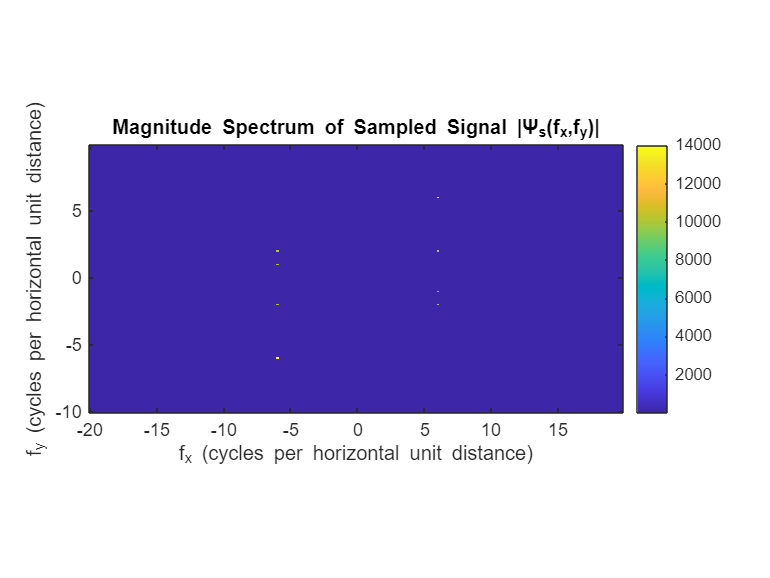

% 2D FFT of the sampled signal:
Psi = fftshift(fft2(psi_s)); % to center the frequency.

% Magnitude spectrum
Psi_mag = abs(Psi);

% log scale for better visibility
% Psi_log = log(1 + Psi_mag);

Nx = size(psi_s, 2);   % # columns
Ny = size(psi_s, 1);   % # rows

dx = V(1,1);   % 1/40: the increment on the x axis
dy = V(2,2);   % 1/20: the increment on the y axis

% x and y axes in frequency:
fx = (-Nx/2:Nx/2-1)/(Nx*dx);
fy = (-Ny/2:Ny/2-1)/(Ny*dy);

figure;
imagesc(fx, fy, Psi_mag);
axis xy;
axis equal tight;
colorbar;

xlabel('f_x (cycles per horizontal unit distance)');
ylabel('f_y (cycles per horizontal unit distance)');
title('Magnitude Spectrum of Sampled Signal |\Psi_s(f_x,f_y)|');

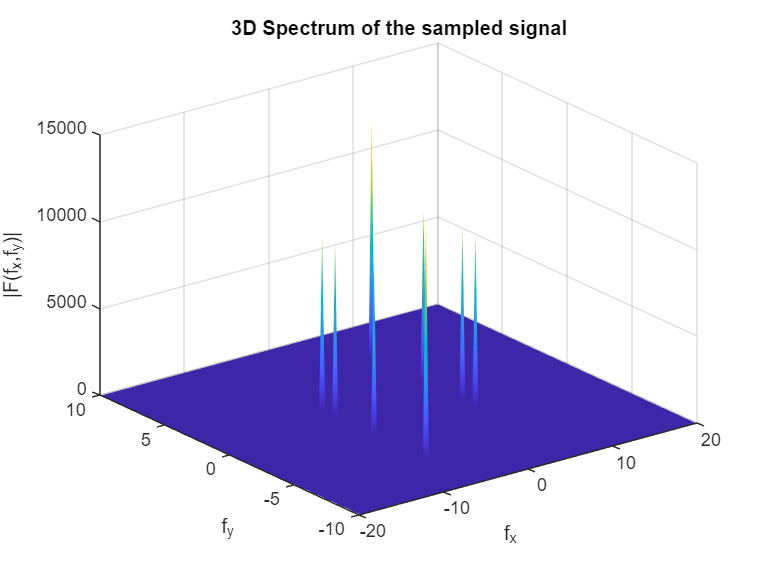


figure;
surf(fx, fy, Psi_mag);
shading interp;
xlabel('f_x'); ylabel('f_y'); zlabel('|F(f_x,f_y)|');
title('3D Spectrum of the sampled signal');

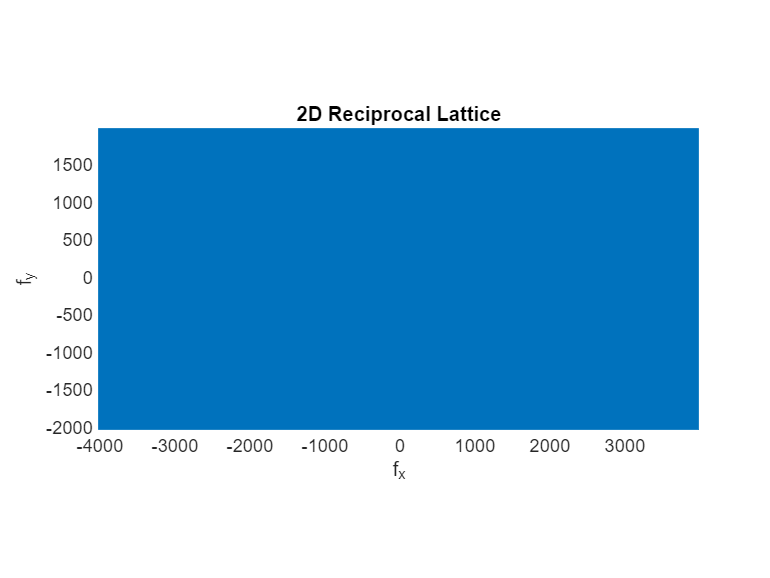

%reciprocal latice
U = inv(V');
m = -N/2*U(1,1):U(1,1):(N/2-1)*U(1,1);
n = -N/2*U(2,2):U(2,2):(N/2-1)*U(2,2);
[f_x,f_y]= meshgrid(m,n);

%2D plot of the reciprocal lattice grid.
figure;
voronoi(f_x,f_y)
%plot(f_x,f_y,'.', 'MarkerSize', 20,'Color', 'b')
title('2D Reciprocal Lattice');
xlabel('f_x'); ylabel('f_y');
axis equal tight;
grid on;

### **Task 2.a:**

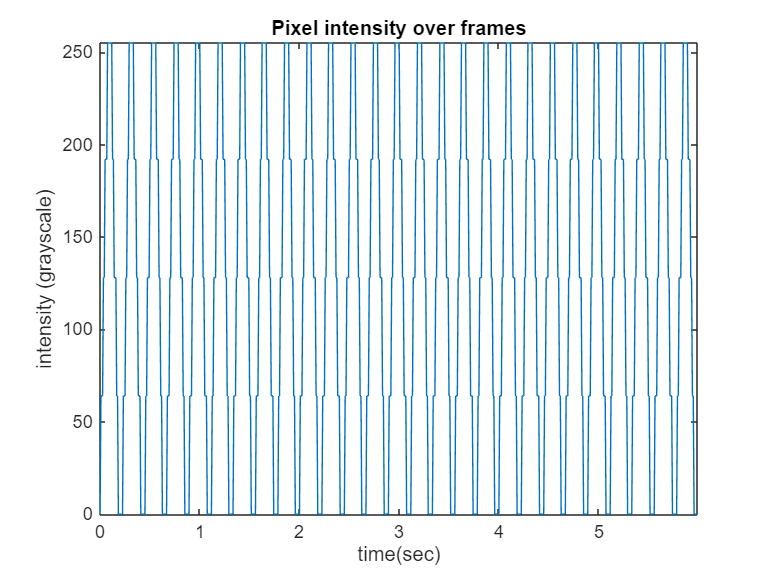

path = "\task2_orig120fps.avi";
vid = VideoReader(path);

c = 20;
d = 30;

%Coords of the pixel:
x = 5*c; 
y = 5*d;

n_frames = vid.NumFrames; %# of frames = diff values of the pixel

pixel_values = zeros(1,n_frames); %array to store the grayscale values of the pixel.
i = 1;
while hasFrame(vid)
    frame = readFrame(vid,'native');
    pixel_values(i) = double(frame.cdata(y,x)); % y: eix vertical (files), x:eix horitzontal (columnes)
    i = i+1;
end

fr = vid.FrameRate; %frame rate = 120 frames/s
time = (0:n_frames-1) / fr;

figure;
plot(time, pixel_values)
xlabel('time(sec)'); ylabel('intensity (grayscale)');
title('Pixel intensity over frames');
axis tight;

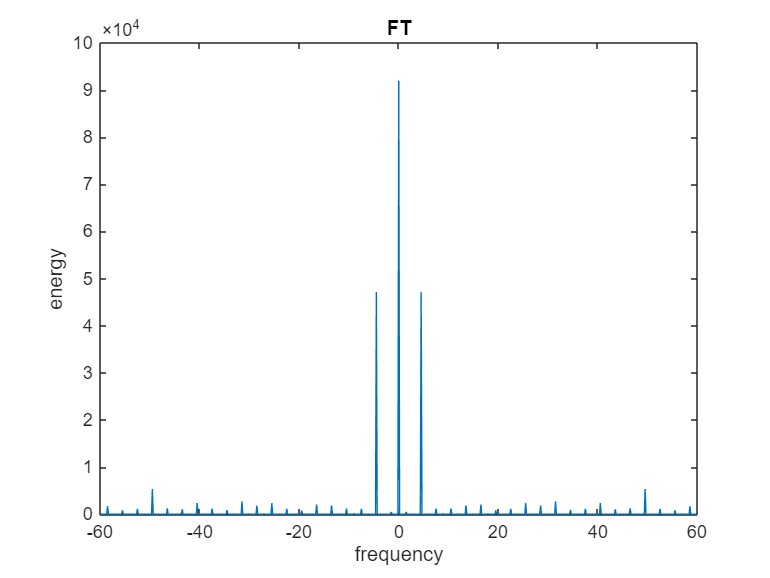


%From the plot above we can recover the period of the intesity of the pixel
%that is 0.45-0.225 = 0.225s. Therefore, the fundamental frequency is
%1/0.225 = 4.44Hz

F_pixel = fftshift(fft(pixel_values));
% Magnitude spectrum
F_mag = abs(F_pixel);

f = (-n_frames/2:n_frames/2-1)*(fr/n_frames); %frequency axis

figure;
plot(f, F_mag)
xlabel('frequency'); ylabel('energy');
title('FT');

clear vid;

### **Task 2.c:**

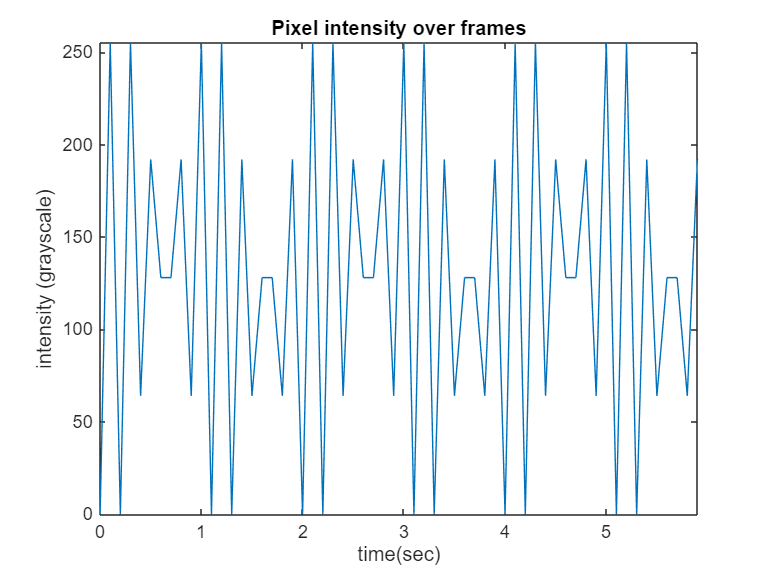

path = "\task2_orig120fps.avi";
vid_120 = VideoReader(path);
vid_10 = VideoWriter("task2_sampled_10Hz.avi");
vid_10.FrameRate = 10;
open(vid_10);
frame_idx = 0;

n_frames = vid_120.NumFrames/12;
pix_val = zeros(1,n_frames);
i = 1;

while hasFrame(vid_120)
    frame = readFrame(vid_120);
    
    if mod(frame_idx, 12) == 0
        writeVideo(vid_10, frame);
        pix_val(i) = frame(y,x);
        i = i + 1; 
    end
    
    frame_idx = frame_idx + 1;
end

close(vid_out);

fr = 10; %frame rate = 10 frames/s
time = (0:size(pix_val,2)-1) / fr;

figure;
plot(time, pix_val)
xlabel('time(sec)'); ylabel('intensity (grayscale)');
title('Pixel intensity over frames');
axis tight;

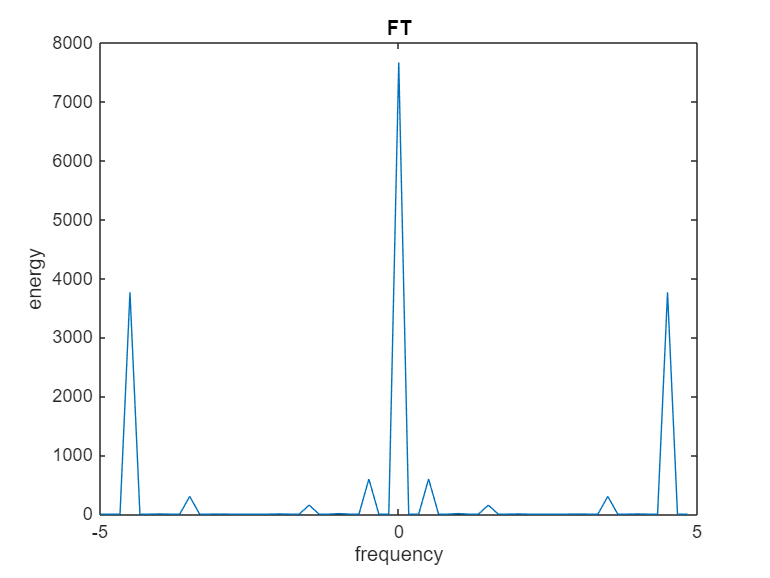


F_pixel = fftshift(fft(pix_val));
% Magnitude spectrum
F_mag = abs(F_pixel);

f = (-size(pix_val,2)/2:size(pix_val,2)/2-1)*(fr/size(pix_val,2)); %frequency axis

figure;
plot(f, F_mag)
xlabel('frequency'); ylabel('energy');
title('FT');

### **Task 2.d**

%% Task: Minimum frame rate to avoid temporal aliasing in the whole video

% Read video
path = "task2_orig120fps.avi";
vid  = VideoReader(path);

fs = vid.FrameRate;          % Original sampling frequency (Hz)
N  = vid.NumFrames;
H  = vid.Height;
W  = vid.Width;

% Preallocate video array (grayscale assumed)
video = zeros(H, W, N);

%% Load video frames
i = 1;
while hasFrame(vid)
    frame = readFrame(vid,'native');
    video(:,:,i) = double(frame.cdata(:,:,1)); % grayscale
    i = i + 1;
end

%% Temporal FFT of each pixel
F = fft(video, [], 3);

% Frequency axis
f = (0:N-1) * fs / N;
half = 1:floor(N/2);

% Magnitude spectrum (positive frequencies only)
Fmag = abs(F(:,:,half));
f_half = f(half);

% Remove DC component
Fmag(:,:,1) = 0;

%% Dominant (fundamental) frequency per pixel
[~, idx] = max(Fmag, [], 3);
f0_map = f_half(idx);

%% Global maximum fundamental frequency
f0_max = max(f0_map(:));

% Minimum sampling frequency (Nyquist)
fs_min = 2 * f0_max;

%% Display results
fprintf('Maximum fundamental frequency in video: %.2f Hz\n', f0_max);

Maximum fundamental frequency in video: 20.33 Hz


fprintf('Minimum sampling frequency to avoid aliasing: %.2f Hz\n', fs_min);

Minimum sampling frequency to avoid aliasing: 40.67 Hz


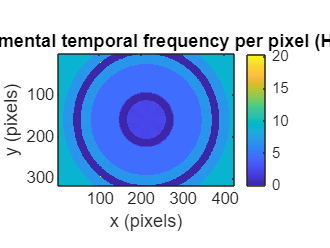


%% Visualization for justification
figure;
imagesc(f0_map);
colorbar;
xlabel('x (pixels)');
ylabel('y (pixels)');
title('Fundamental temporal frequency per pixel (Hz)');
axis image;

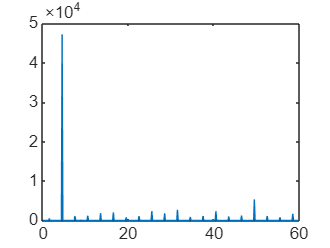

f_xy = squeeze(Fmag(y,x,:));
plot(f_half, f_xy)

path = "\task2_orig120fps.avi";
vid_120 = VideoReader(path);
vid_60 = VideoWriter("task2_sampled_60Hz.avi");
vid_60.FrameRate = 60;
open(vid_60);
frame_idx = 0;

n_frames = vid_120.NumFrames/12;
pix_val = zeros(1,n_frames);
i = 1;

while hasFrame(vid_120)
    frame = readFrame(vid_120);
    
    if mod(frame_idx, 2) == 0
        writeVideo(vid_60, frame);
        pix_val(i) = frame(y,x);
        i = i + 1; 
    end
    
    frame_idx = frame_idx + 1;
end

close(vid_60);


path = "\task2_orig120fps.avi";
vid_120 = VideoReader(path);
vid_30 = VideoWriter("task2_sampled_30Hz.avi");
vid_30.FrameRate = 30;
open(vid_30);
frame_idx = 0;

n_frames = vid_120.NumFrames/12;
pix_val = zeros(1,n_frames);
i = 1;

while hasFrame(vid_120)
    frame = readFrame(vid_120);
    
    if mod(frame_idx, 4) == 0
        writeVideo(vid_30, frame);
        pix_val(i) = frame(y,x);
        i = i + 1; 
    end
    
    frame_idx = frame_idx + 1;
end

close(vid_30);